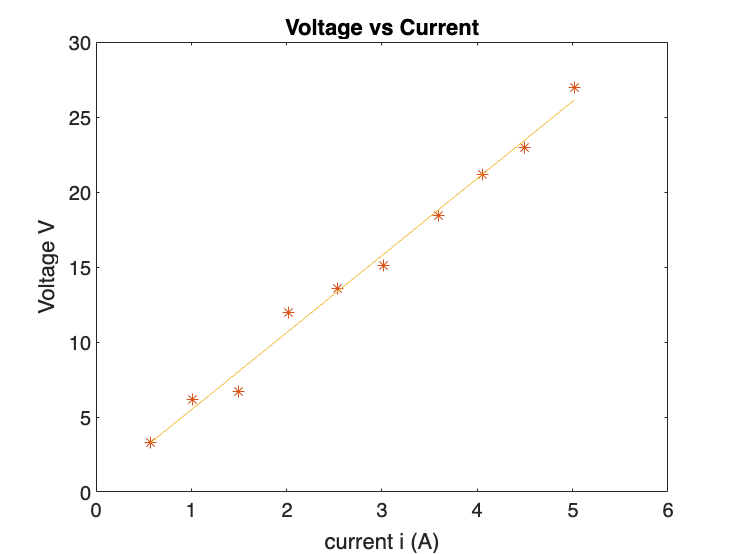

i = [0.57 1.01 1.50 2.02 2.53 3.02 3.59 4.05 4.50 5.02];
V = [3.30 6.16 6.73 11.98 13.60 15.09 18.41 21.19 22.95 26.98];

R = V./i;

plot(i,V,"*"); hold on;
xlabel("current i (A)");
ylabel("Voltage V");
title("Voltage vs Current");
plot(i,V,"*");

meanR = mean(R);
stdDivR = std(R);
p = polyfit(i,V,1);

%Regressive Analysis
Slope_Val = p(1);
Intercept_Val = p(2);


n = length(i);
epsilon = sqrt(sum((V-p(1)*i - p(2)).^2)/(n-2));
delta = n*sum(i.^2) - (sum(i)) ^2;
sigmaa = sqrt(n*epsilon^2/delta);
sigmab = sqrt(epsilon^2*sum(i.^2)/delta);
hold on;
plot(i, p(1)*i+p(2), '-');
hold off;

%Now problem 2


t = [0 1 2 3 4 5 6 7];
v = [3.1 2.0 1.3 0.8 0.5 0.3 0.2 0.1];


semilogy(t,v,"-");
xlabel("Time (T)");
ylabel("Voltage V");